## Scratch editor for developing compute_MP`.m`

clear;
addpath('/Users/p3choi/SIOG230_GNS_Geodesy/SIOG230_GNS_Geodesy/matlab_utils/');
addpath('/Users/p3choi/SIOG230_GNS_Geodesy/SIOG230_GNS_Geodesy/products/');


[obs,t,gps,apr,hant] = ...
    read_rinexo(['/Users/p3choi/SIOG230_GNS_Geodesy/' ...
    'SIOG230_GNS_Geodesy/products/opmt2920.19o']);

-------------
Reading /Users/p3choi/SIOG230_GNS_Geodesy/SIOG230_GNS_Geodesy/products/opmt2920.19o
  approximate position (m): 4202777.622 171367.761 4778659.984
  7 observable types: L1L2C1P1P2S1S2
  sampling interval: 30 seconds
  2880 epochs
  30 GPS satellites
  0 GLONASS satellites
  0 GALILEO satellites
  reading file body -- this part is slow, sorry...



disp(pwd);

/Users/p3choi


% Phase data (L1, L2) is in units of cycles of carrier phase
L1 = obs.L1;
L2 = obs.L2;
% Pseudorange data in meters
C1 = obs.C1;
P1 = obs.P1;
P2 = obs.P2;
%S1 = obs.S1;
%S2 = obs.S2;

f1 = 1.57542*1e9;
f2 = 1.2276*1e9;
c = 0.299792458*1e9

c = 299792458

lambda1 = c/f1;
lambda2 = c/f2;

alpha = (f1/f2)^2;

% L1, L2 --> meters
L1 = L1*lambda1;
L2 = L2*lambda2;
MP1 = P1 - (2/(alpha - 1) + 1) .* L1 + (2/(alpha - 1)) .* L2;
MP2 = P2 - (2*alpha/(alpha-1)).*L1 + (2*alpha/(alpha-1) - 1) .* L2;


% % Find MP1 MP2 for PRN=3
sv = 3;
idx_prn = find(gps == sv);
MP1_sv = MP1(:, idx_prn);
MP2_sv = MP2(:, idx_prn);

% Remove mean from MP1, MP2
MP1_sv = MP1_sv - mean(MP1_sv(~isnan(MP1_sv)));
MP2_sv = MP2_sv - mean(MP2_sv(~isnan(MP2_sv)));

[Y,M,DoM,DoY,GPSW,DoGPSW,SoGPSW,JD,DecY] ...
    = gpsdate(t(:,1)+2000,t(:,2),t(:,3),t(:,4),t(:,5),t(:,6));
t_hrs = t(:,4) + t(:,5)/60 + t(:,6)/3600;
disp(t_hrs);

         0
    0.0083
    0.0167
    0.0250
    0.0333
    0.0417
    0.0500
    0.0583
    0.0667
    0.0750
    0.0833
    0.0917
    0.1000
    0.1083
    0.1167
    0.1250
    0.1333
    0.1417
    0.1500
    0.1583
    0.1667
    0.1750
    0.1833
    0.1917
    0.2000
    0.2083
    0.2167
    0.2250
    0.2333
    0.2417
    0.2500
    0.2583
    0.2667
    0.2750
    0.2833
    0.2917
    0.3000
    0.3083
    0.3167
    0.3250
    0.3333
    0.3417
    0.3500
    0.3583
    0.3667
    0.3750
    0.3833
    0.3917
    0.4000
    0.4083
    0.4167
    0.4250
    0.4333
    0.4417
    0.4500
    0.4583
    0.4667
    0.4750
    0.4833
    0.4917
    0.5000
    0.5083
    0.5167
    0.5250
    0.5333
    0.5417
    0.5500
    0.5583
    0.5667
    0.5750
    0.5833
    0.5917
    0.6000
    0.6083
    0.6167
    0.6250
    0.6333
    0.6417
    0.6500
    0.6583
    0.6667
    0.6750
    0.6833
    0.6917
    0.7000
    0.7083
    0.7167
    0.7250
    0.7333
    0.7417
    0.7500

%disp(SoGPSW/(3600))

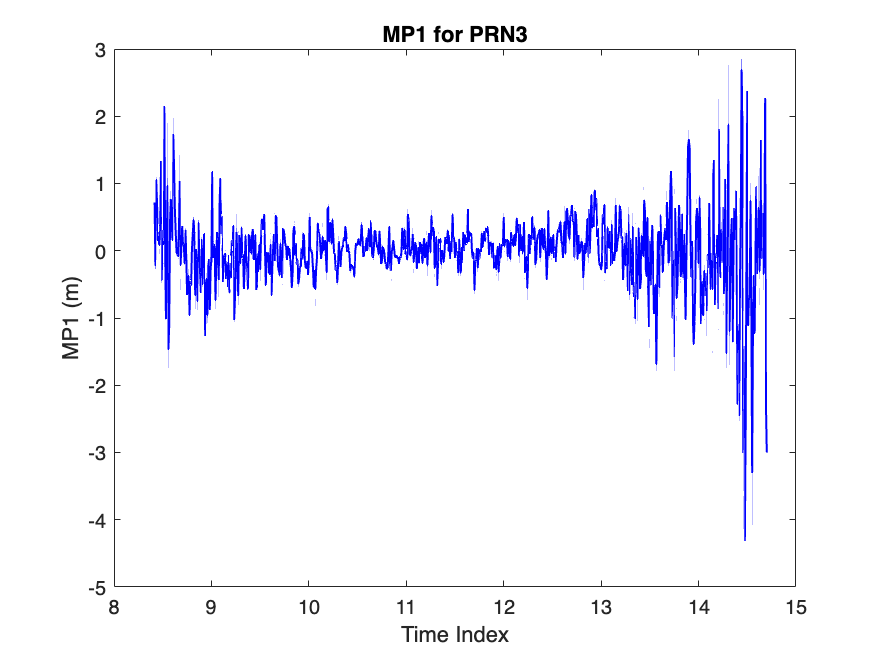

clf;
%hold on;
plot(t_hrs, MP1_sv,"b",LineWidth=1);
title("MP1 for PRN"+sv);
xlabel("Time Index");
ylabel("MP1 (m)");

%hold off;

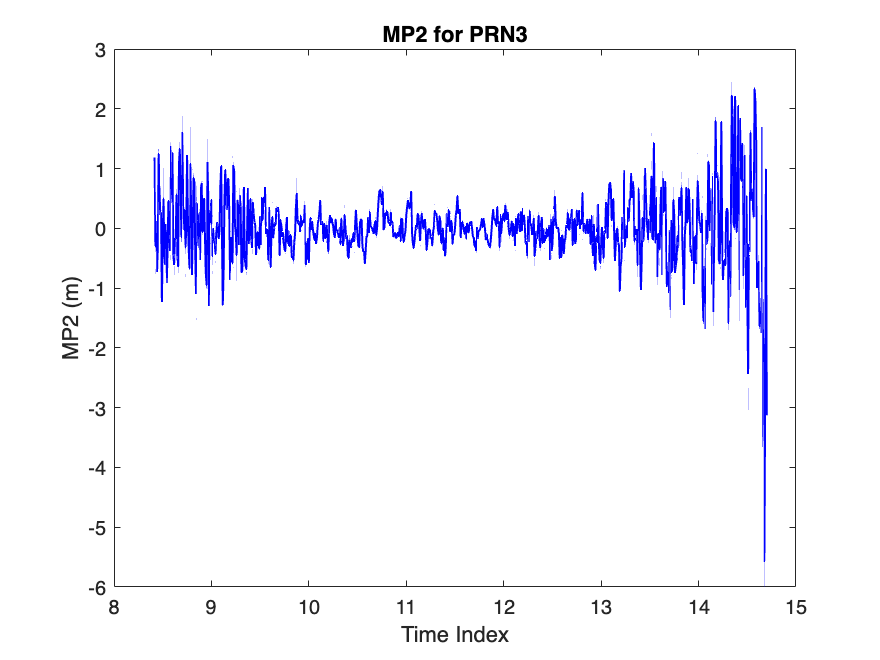

clf;
%hold on;
plot(t_hrs, MP2_sv,"b",LineWidth=1);
title("MP2 for PRN"+sv);
xlabel("Time Index");
ylabel("MP2 (m)");

%hold off;

% % Find MP1 MP2 for PRN=10
sv = 10;
idx_prn = find(gps == sv);

range = [1:2880];

MP1_sv = MP1(range, idx_prn);
MP2_sv = MP2(range, idx_prn);

t_hrs = t(range,4) + t(range,5)/60 + t(range,6)/3600;

% Remove mean from MP1, MP2
MP1_sv = MP1_sv - mean(MP1_sv(~isnan(MP1_sv)));
MP2_sv = MP2_sv - mean(MP2_sv(~isnan(MP2_sv)));

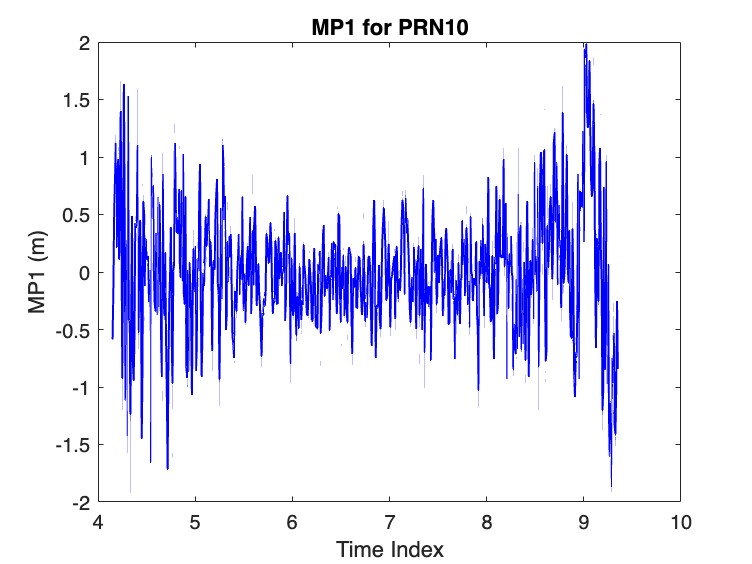

clf;
%hold on;
plot(t_hrs, MP1_sv,"b",LineWidth=1);
title("MP1 for PRN"+sv);
xlabel("Time Index");
ylabel("MP1 (m)");

%hold off;

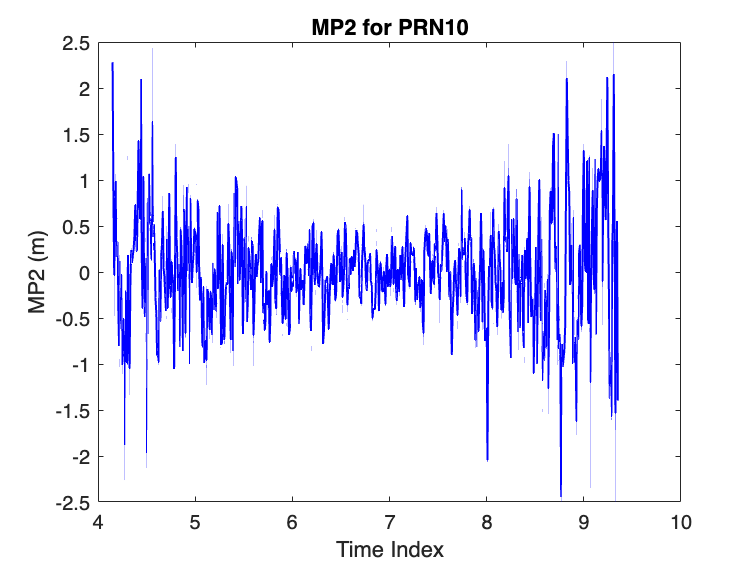

clf;
%hold on;
plot(t_hrs, MP2_sv,"b",LineWidth=1);
title("MP2 for PRN"+sv);
xlabel("Time Index");
ylabel("MP2 (m)");

%hold off;